clear; close all; clc;

%% -------------------- Paths --------------------
load ("D:\Hippocampus Paper\HistCenterTime.mat");   % time vector (1 x T)
% L5 is CA1 for convinience
load("D:\V1_Cortex_Paper\MultichannelDataTanks\GranAverage\Layers\F1F2_matrices_L_5_V1.mat")
DEV_F1_F2_CA1 = F1F2.DEV_F1_F2;
STD_F1_F2_CA1 = F1F2.STD_F1_F2;

% L6 is DG for convinience
load("D:\V1_Cortex_Paper\MultichannelDataTanks\GranAverage\Layers\F1F2_matrices_L_6_V1.mat")
DEV_F1_F2_DG = F1F2.DEV_F1_F2;
STD_F1_F2_DG = F1F2.STD_F1_F2;

t = HistCentersTime(:)';   % enforce row

%% -------------------- MMN per region --------------------
MMN_CA1 = DEV_F1_F2_CA1 - STD_F1_F2_CA1;   % [C1 x T]
MMN_DG  = DEV_F1_F2_DG  - STD_F1_F2_DG;    % [C2 x T]

nCols = size(MMN_DG,2);
p = nan(1,nCols);
for c = 1:nCols
    % choose one:
    % [~,p(c)] = ttest2(MMN_DG(:,c), MMN_CA1(:,c), 'Vartype','unequal');
    p(c) = ranksum(MMN_DG(:,c), MMN_CA1(:,c));
end

% BH-FDR (implement if you don't have fdr_bh.m)
[psort,idx] = sort(p); q = 0.05;
thresh = (1:nCols)/nCols * q;
k = find(psort <= thresh, 1, 'last');
sig_idx = [];
if ~isempty(k)
    cutoff = psort(k);
    sig_idx = find(p <= cutoff);    % columns significant at FDR 5%
end

%% -------- Parameters you can tweak --------
run_len       = 2;        % require 2 consecutive points
post_onset_ms = 0;        % only search at/after this time (e.g., stimulus onset)
base_win_ms   = [-50 0];  % baseline window for subtraction (ms)

t = HistCentersTime(:)';

%% -------- Build baseline mask from HistCentersTime --------
if any(t >= base_win_ms(1) & t <= base_win_ms(2))
    base_mask = t >= base_win_ms(1) & t <= base_win_ms(2);
else
    % Fallback if time axis doesn't cover baseline_win
    base_mask = false(size(t));
    base_mask(5:min(8,numel(t))) = true;
end

%% -------- Compute consecutive-half-max onset for MMN (CA1 & DG) --------
lat_MMN_CA1 = halfmax_consecutive_latency(MMN_CA1, t, base_mask, post_onset_ms, run_len);
lat_MMN_DG  = halfmax_consecutive_latency(MMN_DG,  t, base_mask, post_onset_ms, run_len);

%% -------- Summaries --------
n_CA1 = sum(~isnan(lat_MMN_CA1));
n_DG  = sum(~isnan(lat_MMN_DG));

fprintf('Consecutive-%d half-max onset (MMN CA1): %.3f ms ± %.3f (SEM), n=%d\n', ...
    run_len, mean(lat_MMN_CA1,'omitnan'), std(lat_MMN_CA1,'omitnan'), n_CA1);

Consecutive-2 half-max onset (MMN CA1): 325.000 ms ± 87.777 (SEM), n=30



fprintf('Consecutive-%d half-max onset (MMN DG):  %.3f ms ± %.3f (SEM), n=%d\n', ...
    run_len, mean(lat_MMN_DG,'omitnan'),  std(lat_MMN_DG,'omitnan'),  n_DG);

Consecutive-2 half-max onset (MMN DG):  325.000 ms ± 64.550 (SEM), n=64


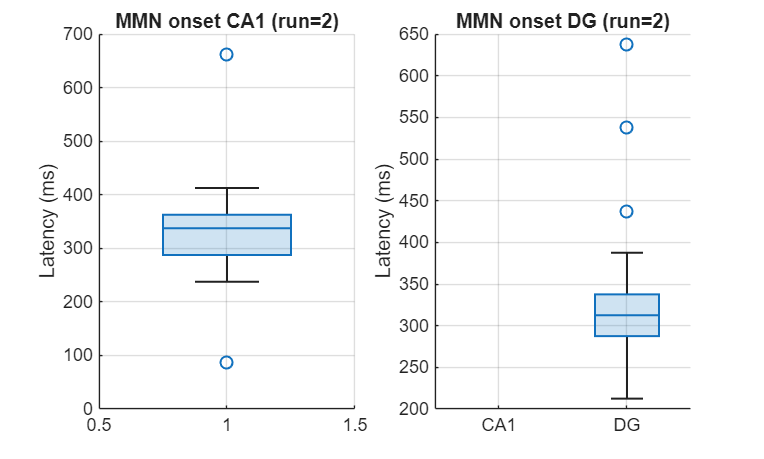


%% (optional) quick visualization
figure('Color','w'); 
subplot(1,2,1);
boxchart(ones(size(lat_MMN_CA1)), lat_MMN_CA1); hold on;
title(sprintf('MMN onset CA1 (run=%d)', run_len)); ylabel('Latency (ms)'); grid on;

subplot(1,2,2);
boxchart(2*ones(size(lat_MMN_DG)),  lat_MMN_DG);  hold on;
title(sprintf('MMN onset DG (run=%d)', run_len)); ylabel('Latency (ms)'); grid on; xlim([0.5 2.5]); xticks([1 2]); xticklabels({'CA1','DG'});

function lat = halfmax_consecutive_latency(X, t, base_mask, post_onset_ms, run_len)
% X: C x T matrix (channels x time)
% t: 1 x T vector of time (ms)
% base_mask: 1 x T logical, baseline window for subtraction
% post_onset_ms: scalar, only search at/after this time
% run_len: integer, required consecutive samples above threshold

    % Baseline-subtract per channel using its own baseline mean
    base_mean = mean(X(:, base_mask), 2, 'omitnan');  % C x 1
    X0 = X - base_mean;                               % C x T

    % Restrict to post-onset window
    post_mask = t >= post_onset_ms;
    tt = t(post_mask);            % 1 x Tp
    Xp = X0(:, post_mask);        % C x Tp

    C = size(X,1);
    lat = nan(C,1);

    % Sliding-window kernel for "run_len consecutive" check
    k = ones(1, run_len);

    for c = 1:C
        r = Xp(c,:);                          % 1 x Tp
        if all(isnan(r)), continue; end

        mx = max(r, [], 2, 'omitnan');        % scalar per channel on post-onset window
        if ~isfinite(mx), continue; end

        thr = mx/2;
        meets = r >= thr;                      % logical: above half-max
        % Count how many "true" within each run_len window; 'valid' aligns to window start
        win_count = conv(double(meets), k, 'valid');

        % Find first window where all run_len are true
        start_idx = find(win_count >= run_len, 1, 'first');
        if ~isempty(start_idx)
            lat(c) = tt(start_idx);           % first of the consecutive points
        end
    end
end

%% -------- CA1 vs DG latency comparison (nonparametric + effect size) --------
lat_CA1 = lat_MMN_CA1(:);
lat_DG  = lat_MMN_DG(:);

% Clean NaNs
lat_CA1 = lat_CA1(isfinite(lat_CA1));
lat_DG  = lat_DG(isfinite(lat_DG));

n1 = numel(lat_CA1);
n2 = numel(lat_DG);

% Summary stats
m_CA1 = mean(lat_CA1);  se_CA1 = std(lat_CA1);
m_DG  = mean(lat_DG);   se_DG  = std(lat_DG);
med_CA1 = median(lat_CA1);
med_DG  = median(lat_DG);

fprintf('\nConsecutive-2 half-max onset (MMN)\n');


Consecutive-2 half-max onset (MMN)


fprintf('CA1: mean = %.2f ms ± %.2f SEM, median = %.2f, n=%d\n', m_CA1, se_CA1, med_CA1, n1);

CA1: mean = 325.00 ms ± 87.78 SEM, median = 337.50, n=30


fprintf(' DG: mean = %.2f ms ± %.2f SEM, median = %.2f, n=%d\n', m_DG,  se_DG,  med_DG,  n2);

 DG: mean = 325.00 ms ± 64.55 SEM, median = 312.50, n=64



% -------- Significance test on latencies (nonparametric) --------
[p_rs,~,stats_rs] = ranksum(lat_DG, lat_CA1);  % Mann–Whitney U test
zval = stats_rs.zval;

% Also (optional) Welch's t-test for reference
[~,p_t,~,stats_t] = ttest2(lat_DG, lat_CA1, 'Vartype','unequal');

% -------- Effect size: Cliff's delta (DG vs CA1) + 95% CI by bootstrap --------
delta = cliffs_delta(lat_DG, lat_CA1);  % DG minus CA1 ordering
B = 10000;
dBoot = zeros(B,1);
rng('default');
for b = 1:B
    xb = lat_DG(randi(n2, n2, 1));
    yb = lat_CA1(randi(n1, n1, 1));
    dBoot(b) = cliffs_delta(xb, yb);
end
ciDelta = quantile(dBoot, [0.025 0.975]);

% -------- Median difference (DG − CA1) with 95% CI (bootstrap) --------
B2 = 10000;
diffBoot = zeros(B2,1);
for b = 1:B2
    xb = lat_DG(randi(n2, n2, 1));
    yb = lat_CA1(randi(n1, n1, 1));
    diffBoot(b) = median(xb) - median(yb);
end
ciDiff = quantile(diffBoot, [0.025 0.975]);
median_diff = med_DG - med_CA1;

% -------- Print results --------
fprintf('\nDG vs CA1 latency comparison:\n');


DG vs CA1 latency comparison:


fprintf('Mann–Whitney ranksum: p = %.4g (z = %.3f)\n', p_rs, zval);

Mann–Whitney ranksum: p = 0.4988 (z = -0.676)


fprintf('Welch t-test (ref):   p = %.4g (t = %.3f, df ≈ %.1f)\n', p_t, stats_t.tstat, stats_t.df);

Welch t-test (ref):   p = 1 (t = 0.000, df ≈ 44.3)


fprintf("Median difference (DG − CA1) = %.2f ms, 95%% CI [%.2f, %.2f]\n", ...
        median_diff, ciDiff(1), ciDiff(2));

Median difference (DG − CA1) = -25.00 ms, 95% CI [-25.00, 12.50]


fprintf("Cliff's delta (DG vs CA1) = %.3f, 95%% CI [%.3f, %.3f]\n", ...
        delta, ciDelta(1), ciDelta(2));

Cliff's delta (DG vs CA1) = 0.018, 95% CI [-0.269, 0.162]


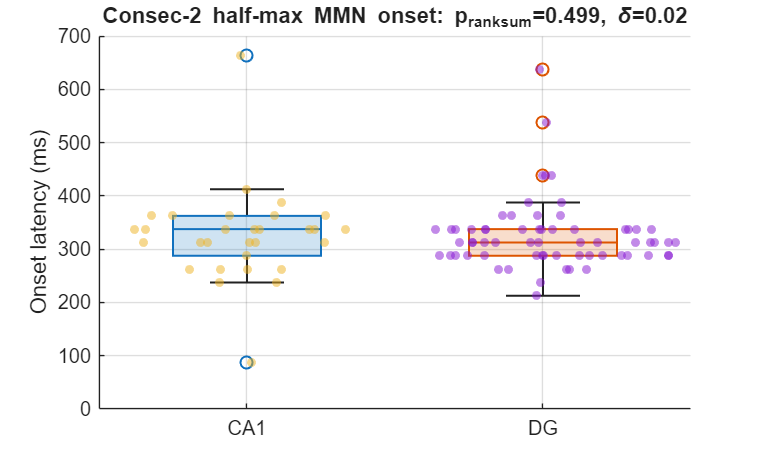


% -------- Quick visualization --------
figure('Color','w'); 
hold on;
boxchart(ones(size(lat_CA1)), lat_CA1);
boxchart(2*ones(size(lat_DG)),  lat_DG);
swarmchart(ones(size(lat_CA1)), lat_CA1, 20, 'filled', 'MarkerFaceAlpha', 0.5);
swarmchart(2*ones(size(lat_DG)), lat_DG, 20, 'filled', 'MarkerFaceAlpha', 0.5);
xlim([0.5 2.5]); xticks([1 2]); xticklabels({'CA1','DG'});
ylabel('Onset latency (ms)');
title(sprintf('Consec-2 half-max MMN onset: p_{ranksum}=%.3g, \\delta=%.2f', p_rs, delta));
grid on;
hold off;


%% -------- Helper: Cliff's delta --------
function d = cliffs_delta(x, y)
% Returns Cliff's delta in [-1, 1]; positive if x tends to be larger than y.
    x = x(:); y = y(:);
    x = x(isfinite(x)); y = y(isfinite(y));
    nX = numel(x); nY = numel(y);
    % Efficient computation using sorting:
    xsorted = sort(x);
    ysorted = sort(y);
    i = 1; j = 1; gt = 0; lt = 0;
    while i <= nX && j <= nY
        if xsorted(i) > ysorted(j)
            gt = gt + (nX - i + 1);  % all remaining x are > y(j)
            j = j + 1;
        elseif xsorted(i) < ysorted(j)
            lt = lt + (nY - j + 1);  % all remaining y are > x(i)
            i = i + 1;
        else
            % handle ties: count how many equal in each
            xi = xsorted(i);
           ii = i + find(xsorted(i+1:end) ~= xi, 1) - 1; if isempty(ii), ii = nX; end
jj = j + find(ysorted(j+1:end) ~= xi, 1) - 1; if isempty(jj), jj = nY; end
            i = ii + 1; j = jj + 1; % ties contribute 0
        end
    end
    d = (gt - lt) / (nX*nY);
end


[res, sig_cols] = welch_per_column(MMN_DG, MMN_CA1, 0.05);

% See significant columns after FDR control:
disp(res(res.sig,:));

    col    mean_DG    mean_CA1    mean_diff      t         df          p          p_fdr       sig     hedges_g
    ___    _______    ________    _________    ______    ______    _________    _________    _____    ________

    28     0.22805    0.020655     0.2074      3.8803    94.991    0.0001924    0.0076959    true     0.64614 




% (Optional) Save results
writetable(res, 'DG_vs_CA1_Welch_per_column.csv');

function [results, sig_idx] = welch_per_column(MMN_DG, MMN_CA1, q)
% Column-wise DG vs CA1 using Welch's t-test with BH-FDR correction.
% Inputs:
%   MMN_DG  : [nDG x nCols]
%   MMN_CA1 : [nCA1 x nCols]
%   q       : FDR level (default 0.05)
% Outputs:
%   results : table with per-column stats (means, diff, t, df, p, p_fdr, sig)
%   sig_idx : indices of columns significant at FDR q

    if nargin < 3 || isempty(q), q = 0.05; end
    assert(size(MMN_DG,2)==size(MMN_CA1,2), 'DG and CA1 must have same # of columns.');

    nCols = size(MMN_DG,2);
    p      = nan(nCols,1);
    tstat  = nan(nCols,1);
    df     = nan(nCols,1);
    mDG    = nan(nCols,1);
    mCA1   = nan(nCols,1);
    mdiff  = nan(nCols,1);   % DG - CA1
    g      = nan(nCols,1);   % Hedges' g (optional effect size)

    for c = 1:nCols
        x = MMN_DG(:,c); x = x(~isnan(x));
        y = MMN_CA1(:,c); y = y(~isnan(y));

        mDG(c)   = mean(x,'omitnan');
        mCA1(c)  = mean(y,'omitnan');
        mdiff(c) = mDG(c) - mCA1(c);

        if numel(x) >= 2 && numel(y) >= 2
            [~, p(c), ~, stats] = ttest2(x, y, 'Vartype','unequal'); % Welch
            tstat(c) = stats.tstat;
            df(c)    = stats.df;

            % --- Optional: Hedges' g (using pooled SD) ---
            n1 = numel(x); n2 = numel(y);
            s1 = std(x,0); s2 = std(y,0);
            sp = sqrt(((n1-1)*s1^2 + (n2-1)*s2^2) / (n1+n2-2));
            if sp > 0
                d = (mean(x)-mean(y)) / sp;
                J = 1 - 3/(4*(n1+n2)-9);  % small-sample correction
                g(c) = J*d;
            end
        end
    end

    % --- Benjamini–Hochberg FDR (uses mafdr if available, else fallback) ---
    [p_fdr, sig_mask] = fdr_bh_local(p, q);
    sig_idx = find(sig_mask);

    results = table((1:nCols)', mDG, mCA1, mdiff, tstat, df, p, p_fdr, sig_mask, g, ...
        'VariableNames', {'col','mean_DG','mean_CA1','mean_diff','t','df','p','p_fdr','sig','hedges_g'});
end

function [p_fdr, sig] = fdr_bh_local(p, q)
% Returns BH-adjusted p-values and significance mask at level q.
    m = numel(p);
    p_fdr = nan(m,1);
    sig   = false(m,1);

    % If Bioinformatics Toolbox is available, use mafdr
    if exist('mafdr','file') == 2
        p_fdr = mafdr(p,'BHFDR',true);
        sig   = p_fdr <= q;
        return
    end

    % Manual BH adjustment (ignores NaNs)
    [ps, idx] = sort(p);
    notnan = ~isnan(ps);
    psn = ps(notnan);
    mn = numel(psn);
    if mn == 0, return; end

    % Adjusted p-values (q-values) with monotonicity
    adj = psn .* mn ./ (1:mn)';
    for i = mn-1:-1:1
        adj(i) = min(adj(i), adj(i+1));
    end

    p_fdr(idx(notnan)) = adj;
    sig = p_fdr <= q;
end


% Means and SEMs across channels
[mu_CA1, sem_CA1] = mean_sem(MMN_CA1, 1);
[mu_DG,  sem_DG ] = mean_sem(MMN_DG,  1);

%% -------------------- Per-time Welch t-test: CA1 vs DG (MMN) --------------------
% Two-sample Welch t-test at each time bin
nT = numel(t);
p  = nan(1,nT);
h  = false(1,nT);
d  = nan(1,nT);      % Cohen's d (pooled SD) for info
for k = 1:nT
    x = MMN_CA1(:,k); x = x(~isnan(x));
    y = MMN_DG(:,k);  y = y(~isnan(y));
    if numel(x) >= 3 && numel(y) >= 3 && any(x~=0) || any(y~=0)
        [~,p(k)] = ttest2(x, y, 'Vartype','unequal');  % Welch
        d(k)     = cohend(x, y);
    end
end

% Benjamini-Hochberg FDR (q = 0.05)
q = 0.05;
[h_fdr, p_fdr] = fdr_bh(p, q);

fprintf('\n=== MMN CA1 vs DG (per time bin) ===\n');


=== MMN CA1 vs DG (per time bin) ===


fprintf('FDR q = %.3f. Significant bins: %d / %d\n', q, sum(h_fdr), nT);

FDR q = 0.050. Significant bins: 1 / 40



%% -------------------- Plot MMN with significance overlay --------------------
figure('Color','w'); hold on;
% Mean ± SEM
shadedErrorBar(t, mu_CA1, sem_CA1, 'lineProps', {'b','LineWidth',1.8});
shadedErrorBar(t, mu_DG,  sem_DG,  'lineProps', {'r','LineWidth',1.8});
yline(0,'k:');

% Significance ribbon (bottom line where h_fdr==1)
yl = ylim;
sig_y = yl(1) + 0.05*range(yl);
plot(t, nanmask(h_fdr, sig_y), 'k', 'LineWidth', 3);
legend({'CA1 MMN','', 'DG MMN','', '0', 'FDR-significant'}, 'Location','best');

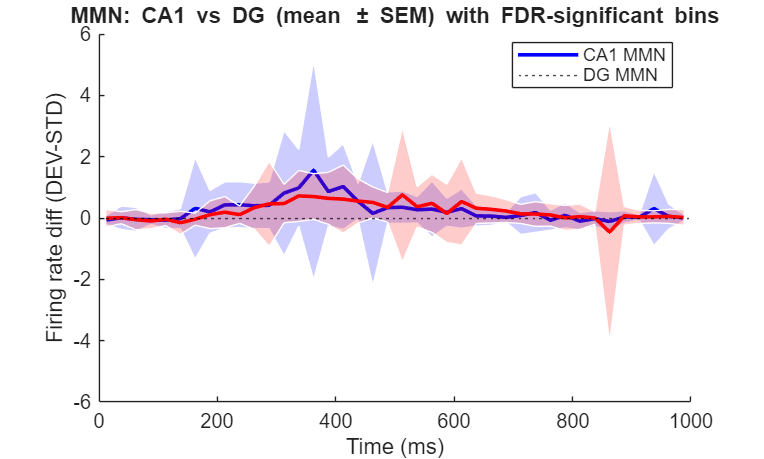

xlabel('Time (ms)'); ylabel('Firing rate diff (DEV-STD)');
title('MMN: CA1 vs DG (mean \pm SEM) with FDR-significant bins');

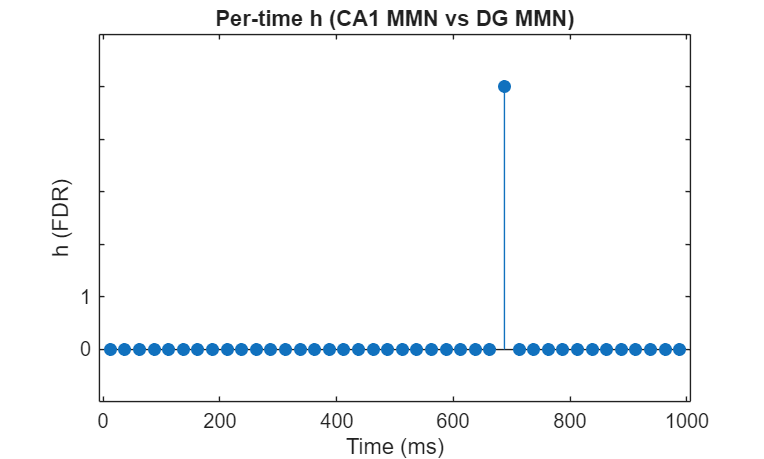


% Optional: binary h plot
figure('Color','w'); 
stem(t, double(h_fdr), 'filled');
ylim([-0.2 1.2]); yticklabels({'','0','1'});
xlabel('Time (ms)'); ylabel('h (FDR)'); title('Per-time h (CA1 MMN vs DG MMN)');


%% -------------------- Consecutive-2 half-max onset (DEV & STD) --------------------
run_len       = 2;           % consecutive-2
post_onset_ms = 0;           % search from 0 ms
base_win_ms   = [-50 0];     % baseline window

% Build baseline mask from t
if any(t >= base_win_ms(1) & t <= base_win_ms(2))
    base_mask = t >= base_win_ms(1) & t <= base_win_ms(2);
else
    base_mask = false(size(t));
    idx = 5:min(8,numel(t)); base_mask(idx) = true;
end

% Onsets
lat_DEV_CA1 = halfmax_consecutive_latency(DEV_F1_F2_CA1, t, base_mask, post_onset_ms, run_len);
lat_STD_CA1 = halfmax_consecutive_latency(STD_F1_F2_CA1, t, base_mask, post_onset_ms, run_len);
lat_DEV_DG  = halfmax_consecutive_latency(DEV_F1_F2_DG,  t, base_mask, post_onset_ms, run_len);
lat_STD_DG  = halfmax_consecutive_latency(STD_F1_F2_DG,  t, base_mask, post_onset_ms, run_len);

fprintf('\n=== Consecutive-%d half-max onsets (ms, mean ± SEM) ===\n', run_len);


=== Consecutive-2 half-max onsets (ms, mean ± SEM) ===


summ_line('DEV  CA1', lat_DEV_CA1);

DEV  CA1: 327.155 ± 83.055 (SEM), n=29


summ_line('DEV  DG ', lat_DEV_DG );

DEV  DG : 318.269 ± 62.307 (SEM), n=65


summ_line('STD  CA1', lat_STD_CA1);

STD  CA1: 375.000 ± 118.673 (SEM), n=16


summ_line('STD  DG ', lat_STD_DG );

STD  DG : 320.357 ± 237.463 (SEM), n=35


%% ==================== Helper functions ====================

function [mu, sem] = mean_sem(X, dim)
    if nargin < 2, dim = 1; end
    mu  = mean(X, dim, 'omitnan');
    n   = sum(~isnan(X), dim);
    sd  = std(X, 0, dim, 'omitnan');
    sem = sd;
end

function y = nanmask(mask, val)
    y = nan(size(mask));
    y(mask) = val;
end

function d = cohend(x, y)
    x = x(:); y = y(:);
    nx = sum(~isnan(x)); ny = sum(~isnan(y));
    mx = mean(x,'omitnan'); my = mean(y,'omitnan');
    sx = std(x,0,'omitnan'); sy = std(y,0,'omitnan');
    sp = sqrt(((nx-1)*sx.^2 + (ny-1)*sy.^2) / max(nx+ny-2,1));
    d  = (mx - my) / sp;
end

function [h, p_fdr, crit_p] = fdr_bh(p, q)
    % Benjamini–Hochberg FDR for vector p
    if isrow(p), p = p'; end
    m = sum(~isnan(p));
    [ps, idx] = sort(p, 'ascend', 'MissingPlacement','last');
    thresh = (1:m)'/m * q;
    below  = find(ps <= thresh);
    if isempty(below)
        crit_p = 0; k = 0;
    else
        k = max(below);
        crit_p = ps(k);
    end
    h = false(size(p));
    if k > 0
        h(idx(1:k)) = true;
    end
    p_fdr = p; % (for completeness—uncorrected p's; use h with FDR)
    h = h';
    p_fdr = p_fdr';
end


function summ_line(lbl, v)
    n = sum(~isnan(v));
    m = mean(v,'omitnan');
    s = std(v,'omitnan');
    fprintf('%-7s: %.3f ± %.3f (SEM), n=%d\n', lbl, m, s, n);
end

function out = best_group_test(x, y, label)
% Choose test by normality; report h, p, effect size.
    x = x(~isnan(x)); y = y(~isnan(y));
    nx = numel(x); ny = numel(y);
    % guard
    if nx < 3 || ny < 3
        warning('%s: too few observations (nx=%d, ny=%d). Returning NaNs.', label, nx, ny);
        out = struct('test','NA','h',0,'p',NaN,'effect',NaN,'effect_name','NA');
        return;
    end

    % Normality checks (Lilliefors); fall back if not available
    Lx = try_lillie(x); Ly = try_lillie(y);
    normal = (Lx==0 && Ly==0); % 0 => fail to reject normality

    if normal
        % Welch's t-test (robust to unequal variances)
        [h,p,~,st] = ttest2(x, y, 'Vartype','unequal');
        % Hedges' g (small-sample bias corrected d)
        g = hedges_g(x, y);
        out = struct('test','Welch t','h',h,'p',p,'tstat',st.tstat,'effect',g,'effect_name','Hedges_g');
    else
        % Wilcoxon rank-sum + Cliff's delta
        p = ranksum(x, y);
        h = double(p < 0.05);
        delta = cliffs_delta(x, y);
        out = struct('test','Rank-sum','h',h,'p',p,'effect',delta,'effect_name','Cliffs_delta');
    end

    fprintf('\n[%s] %s: h=%d, p=%.4g, effect %s=%.3f\n', out.test, label, out.h, out.p, out.effect_name, out.effect);
end

function L = try_lillie(v)
    % 0 = normal (fail to reject); 1 = non-normal (reject)
    try
        [L,~] = lillietest(v);
    catch
        % Fallback: Kolmogorov-Smirnov against normal with sample mean/SD
        v = v(:);
        v = (v-mean(v))/std(v);
        [L,~] = kstest(v);
    end
end

function g = hedges_g(x, y)
    x = x(:); y = y(:);
    nx = numel(x); ny = numel(y);
    mx = mean(x); my = mean(y);
    sx = std(x,0); sy = std(y,0);
    sp = sqrt(((nx-1)*sx.^2 + (ny-1)*sy.^2) / max(nx+ny-2,1));
    d  = (mx - my) / sp;
    J  = 1 - (3/(4*(nx+ny)-9)); % small-sample correction
    g  = J * d;
end

function boxchart_grouped(x, y, labels2)
    % Simple side-by-side box chart
    hold on;
    bx1 = boxchart(ones(size(x)), x); 
    bx2 = boxchart(2*ones(size(y)), y);
    set(bx1,'BoxFaceColor',[0.3 0.5 0.9]); %#ok<*NASGU>
    set(bx2,'BoxFaceColor',[0.9 0.4 0.4]);
    xlim([0.5 2.5]); xticks([1 2]); xticklabels(labels2);
    grid on;
end